# Lecture 1. Image Representation

## **1. Digital image**

- A function of two variables *f*(*x,y*) is often depicted graphically in the form of an *image*

- An image is represented as a matrix (array of numbers) in MATLAB and is referred to as an *image array*

- Each entry of the image array represents an image element called a *pixel*

- Each pixel is assigned an intensity value to illustrate the color of the image (color, grayscale or binary [0's and 1's])

Basic MATLAB functions for reading, displaying, and writing images:

`imread, imshow, imagesc, imwrite`

### 1.1 Binary image

The image array that only consists of 0's and 1's.

***Example 1.1***

A simple binary pattern.

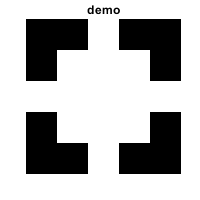

IB=[0 0 1 0 0
    0 1 1 1 0
    1 1 1 1 1
    0 1 1 1 0
    0 0 1 0 0]; % The 2-D image array

figure;
imagesc(IB);
colormap('gray');
axis image;
axis off; % remove axis from the image
axis equal; % use equal data unit lengths along each axis
title('demo');
xlabel('x_0 axis');
set(gcf,'Position',[100 100 200 200]); % set the position and size of the image

***Example 1.2 ***

A circle with variable radius. 

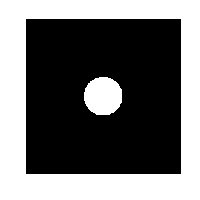

x = 1:256; 
y = 1:256;
[X,Y] = ndgrid(x,y);

F = zeros(256,256);
r =32; % radius of the circle
Cx = 128; % center of the circle x-coordinate
Cy = 128; % center of the circle y-coordinate
F((X-Cx).^2+(Y-Cy).^2<r^2)=1; % circle equation

figure;
imagesc(F);
colormap('gray');
axis image;
axis equal;
axis off;
set(gcf,'Position',[100 100 200 200]);

### 1.2 Gray-scale image

The intensity of a gray-scale image is an integer value in the range [0,255] for 8-bit images and [0,65535] for 16-bit images.

***Example 1.3 ***

Two-dimensional Guassian function (try increasing the number of pixels for finer sampling).

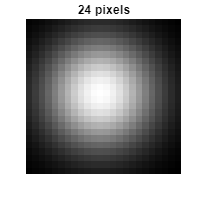

N =24; % number of pixels
x = 1:N;
y = 1:N;
[X,Y]=ndgrid(x,y);

sigma = N/4; % standard deviation
F=exp(-((X-N/2).^2+(Y-N/2).^2)./(2*sigma^2)); % Gaussian function

figure;
imagesc(F);
colormap('gray'); 
axis image;
axis off;
axis equal;
set(gcf,'Position',[100 100 200 200]);
title([num2str(N),' pixels']);

### 1.3 Indexed color image

Instead of using a gray scale, indexed color image defines a colormap that converts the index to a specific color.

***Example 1.4***

Display a Bayer pattern by simply defining a colormap with RGB (red, green, blue) colors.

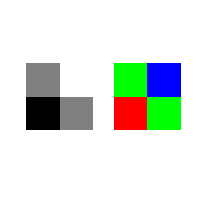

 x=[2,3;
   1,2];
dup=ones(32); % Making the block 32*32 pixels
X=kron(x,dup);

map=[1 0 0  % Red
     0 1 0  % Green
     0 0 1];% Blue

Color_X=zeros([size(X),3]);
[Color_X(:,:,1),Color_X(:,:,2),Color_X(:,:,3)]=ind2rgb(X,map);

figure;
subplot(121);
imagesc(X);
axis image;
axis off;
colormap(gray);
subplot(122);
imagesc(Color_X);
axis image;
axis off;
set(gcf,'Position',[100 100 200 200]);

***Example 1.5***

A pseudocolor display of a transmission x-ray image of a bag.

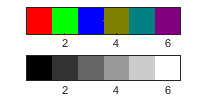

map=[1 0 0        % Red
     0 1 0        % Green
     0 0 1        % Blue
     0.5 0.5 0    % Yellow
     0 0.5 0.5    % Cyan
     0.5 0 0.5];  % Magenta
n_idx=size(map,1); % number of colors
bar=1:n_idx;

figure;
color_bar=ind2rgb(bar,map); % converts the matrix X and corresponding colormap map to RGB (truecolor) format

subplot(211);
imagesc(color_bar);
set(gca,'YTick',[]); % remove the y-axis tick marks
subplot(212);
imagesc(bar);
set(gca,'YTick',[]); % remove the y-axis tick marks
colormap(gray);
set(gcf,'Position',[100 100 200 100]);

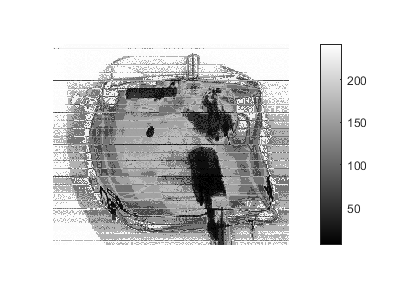

figure;
Img=imread('bag.png');
Img_n=255-Img;

imagesc(Img_n);
colormap('gray');
axis off;
axis equal;
colorbar;
set(gcf,'Position',[100 100 400 300]);

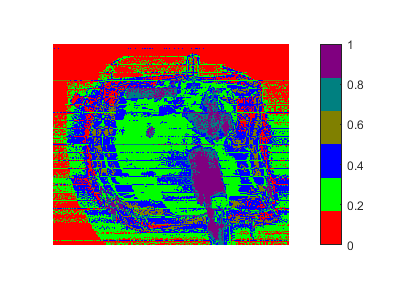

figure;
Img_n=round(double(Img)/double(max(Img(:))) * n_idx);
Img_clr=ind2rgb(Img_n,map);
imagesc(Img_clr);
colormap(map);
axis off;
axis equal;
colorbar;
set(gcf,'Position',[100 100 400 300]);

## 2. Image transformation

An image $f\left(x,y\right)$ can be transformed to another image $g\left(x,y\right)$ by modifying its value at each point $\left(x,y\right)$ in accordance with a mathematical rule (mapping). Here we introduce two fundamental transformations: 

- Geometrical transformations (linear)

- Gray-scale transformations

### 2.1 Coordinate transformation

Geometrical transformation, $f\left(x,y\right)\to g\left(x,y\right)$, followed by a defined coordinate transformation $\left(x,y\right)\to \left(u,v\right)$,

$\left\lbrace \begin{array}{l}
u=u\left(x,y\right)\\
v=v\left(x,y\right)
\end{array}\right.$.

The geometric transformation $f\left(x,y\right)\to g\left(x,y\right)$ follows $g\left(u\left(x,y\right),v\left(x,y\right)\right)=f\left(x,y\right)$. When the coordinate transformation is a linear one, we call the corresponding image transformation **linear geometric transformation**.

#### 2.1.1 Image translation (shift)

Image translation transformation equation

 
$$g\left(x+x_0 ,y+y_0 \right)=f\left(x,y\right)$$


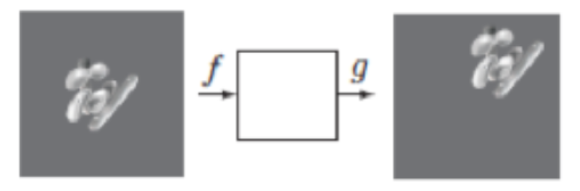

**ILL. 2.1 ***Image translation transformation*

***Example 2.1***

`Y = circshift(`[`A`](https://www.mathworks.com/help/matlab/ref/circshift.html#bt5nt1s-1-A)`,`[`K`](https://www.mathworks.com/help/matlab/ref/circshift.html#bt5nt1s-1-K)`)` circularly shifts the elements in array `A` by `K` positions.

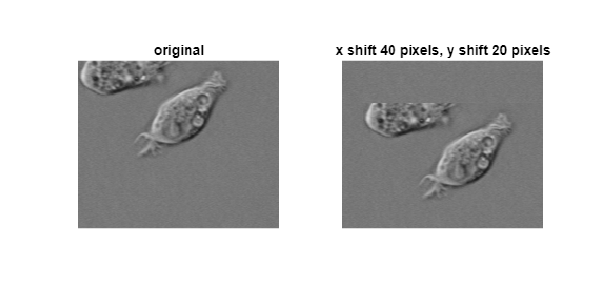

Img=imread('cell.tif');
figure;

x0=40;
y0=20;
Img_t=circshift(Img, [x0,y0]);
figure;
subplot(121);
imshow(Img); 
title('original');
subplot(122);
imshow(Img_t);
title(['x shift ',num2str(x0), ' pixels, y shift ', num2str(y0),' pixels']);
set(gcf,'Position',[100 100 600 300]);

#### 2.1.2 Image rotation

Image rotation transformation equation

 
$$g\left(x\cdot \cos \theta -y\cdot \sin \theta ,x\cdot \sin \theta +y\cdot \cos \theta \right)=f\left(x,y\right)$$


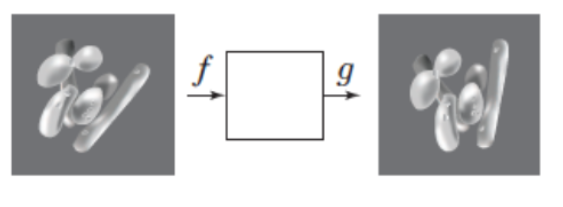

**ILL. 2.2** *Image rotation transformation*

***Example 2.2***

`Y = imrotate(`[`I`](https://www.mathworks.com/help/images/ref/imrotate.html?searchHighlight=imrotate&s_tid=srchtitle_imrotate_1#buxwj90-1-A)`,`[`angle`](https://www.mathworks.com/help/images/ref/imrotate.html?searchHighlight=imrotate&s_tid=srchtitle_imrotate_1#buxwj90-1-angle)`)` rotates image `I` by `angle` degrees in a counterclockwise direction around its center point.

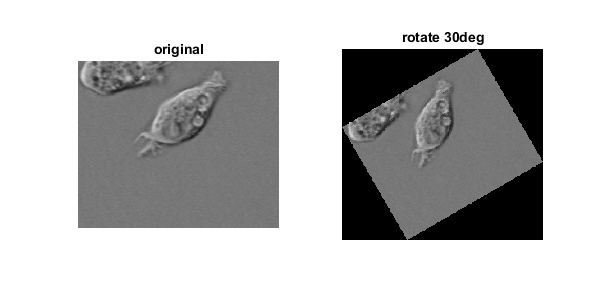

theta=30;
Img_r=imrotate(Img, theta);
figure;
subplot(121);
imshow(Img);
title('original');
subplot(122);
imshow(Img_r);
set(gcf,'Position',[100 100 600 300]);
title(['rotate ',num2str(theta), 'deg']);

#### 2.1.3 Linear image scaling

Linear image scaling transformation equation.

 
$$g\left(s_x ,s_y \right)=f\left(x,y\right)$$


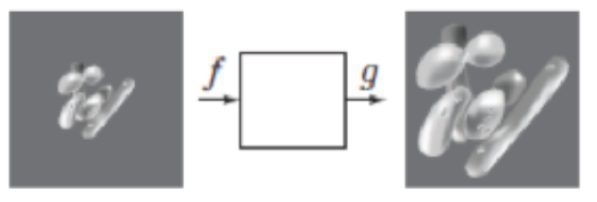

**ILL. 2.3** *Linear image scaling transformation*

***Example 2.3:***

`Y = imresize(`[`A`](https://www.mathworks.com/help/matlab/ref/imresize.html#d124e762813)`,`[`scale`](https://www.mathworks.com/help/matlab/ref/imresize.html#d124e762858)`)` returns image Y that is `scale` times the size of image `A`.

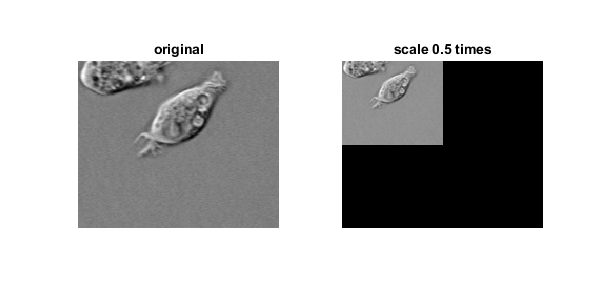

s=0.5;
[m,n]=size(Img);
Img_s=zeros(m,n);
Img_s0=imresize(Img,s);

[m0,n0]=size(Img_s0);
if s>1
    Img_s=Img_s0(1:m,1:n);
else
    Img_s(1:m0,1:n0)=Img_s0;
end

figure;
subplot(121);
imagesc(Img);
axis image;
axis off;
title('original');

subplot(122);
imagesc(Img_s);
axis image;
axis off;
colormap('gray');
title(['scale ',num2str(s),' times']);
set(gcf,'Position',[100 100 600 300]);

### 2.2 Gray-scale transformations

In contrast to geometric transformation, gray-scale transformation$f\left(x,y\right)\to g\left(x,y\right)$ does not involve coordinate transformation. More specifically, the value $g$ at point $\left(x,y\right)$ is determined only by the original image value$f$ at point $\left(x,y\right)$. 

The transformation $f\left(x,y\right)\to g\left(x,y\right)$ follows $g\left(x,y\right)=\Phi \left\lbrace f\left(x,y\right)\right\rbrace$or $g=\Phi \left\lbrace f\right\rbrace$, since the coordinate is the same. The common gray-scale transformations include Gamma transformation, inversion, and quantization.

#### **2.2.1 Gamma transformation**

The Gamma transformation $g=f^{\textrm{𝛾}}$ is common in photography. The coefficient $\textrm{𝛾}$ is called the *contrast index*. 

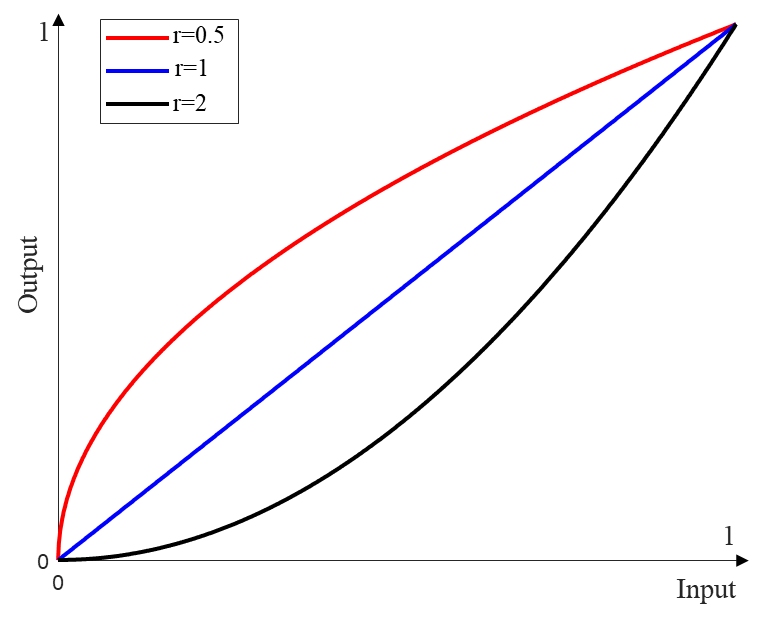

**ILL. 2.4** *Gamma transformation*

***Example 2.4***

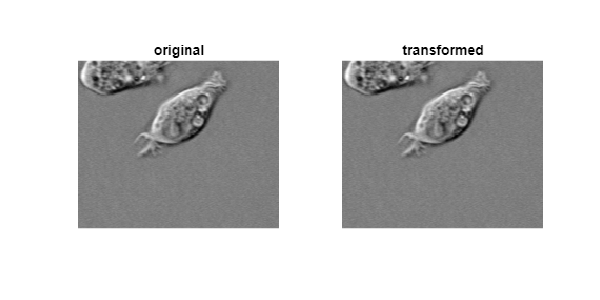

Img=imread('cell.tif');
Img2=double(Img)./255;
figure;
subplot(121);
imagesc(Img2);
colormap('gray');
axis image;
axis off;
title('original');

g =1; % gamma value
Img2_g= Img2.^g;

subplot(122);
imagesc(Img2_g);
colormap('gray');
axis image;
axis off;
title('transformed');
axis equal;
set(gcf,'Position',[100 100 600 300]);

**Contrast**


$$\textrm{Contrast}=\frac{I_{\max } -I_{\min } }{I_{\max } +I_{\min } }$$


Contrast is a real number between 0 and 1. Larger contrast (closer to 1) shows larger variance among pixel values. If the image does not have variance, i.e., $I_{\max } =I_{\min }$, the contrast is 0. Try different $\gamma$ values and see how the contrast changes.

% calculate the contrast
i_max=double(max(max(Img2_g))),

i_max = 0.8314

i_min=double(min(min(Img2_g))),

i_min = 0.1098

contrast=(i_max-i_min)/(i_max+i_min),

contrast = 0.7667

#### 2.2.1 Negative image

Historically, in photography, the photos are developed from films, which is usually on a strip of transparent substrate. The light exposed area usually has high absorption, which makes it dark. The image on the film is usually called photo negative. 

Negative image = Maximum pixel value - Positive Image

***Example 2.5***

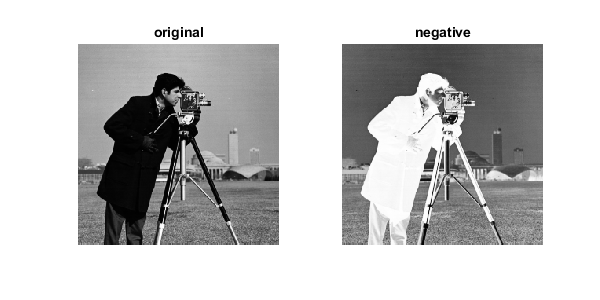


Img=imread('cameraman.tif');
Img_n=255-Img; % 8-bit image, maxium pixel value is 255.

figure;
subplot(121);
imagesc(Img);
colormap(gray)
axis image;
axis off;
title('original');

subplot(122);
imagesc(Img_n);
colormap(gray);
axis image;
axis off;
axis equal;
title('negative');
set(gcf,'Position',[100 100 600 300]);

#### 2.2.2 **Quantization**

Quantization is a transformation which assigns discrete values to the original range of the continous gray scale value, resulting in a fixed-point valued image.

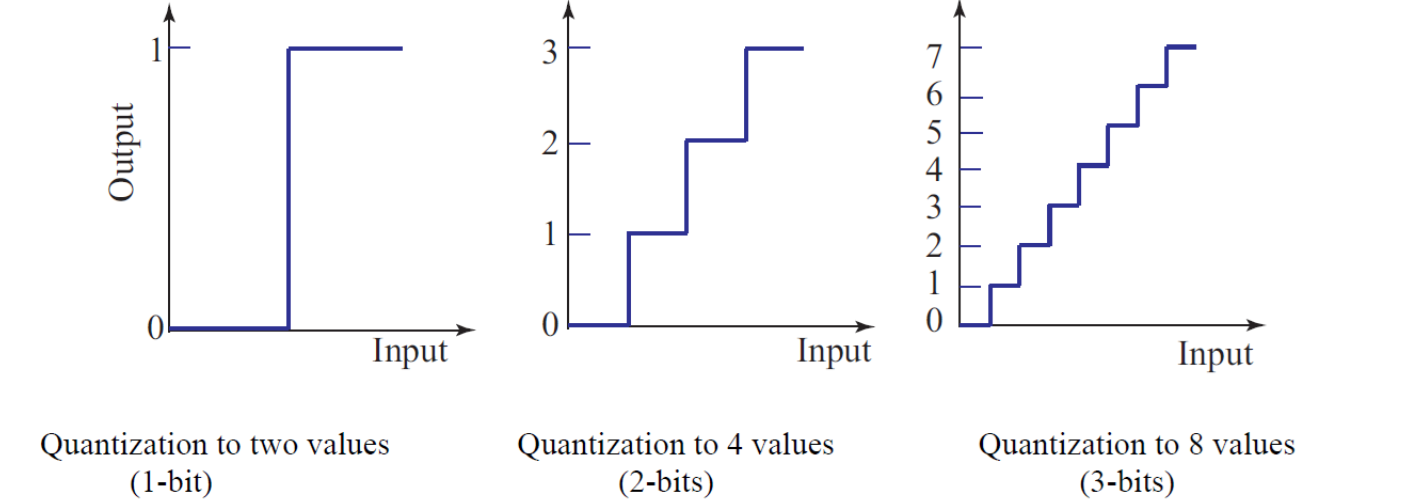

**ILL. 2.5 ***Quantization 1, 2, 3 bits*

***Example 2.6***

[`thresh`](https://www.mathworks.com/help/images/ref/multithresh.html#btj8y4v-thresh)` = multithresh(`[`A`](https://www.mathworks.com/help/images/ref/multithresh.html#btj8y4v-A)`,`[`N`](https://www.mathworks.com/help/images/ref/multithresh.html#btj8y4v-N)`);` returns `thresh` a 1-by-N vector containing `N` threshold values using Otsu’s method. You can use `thresh` as an input argument to [`imquantize`](https://www.mathworks.com/help/images/ref/imquantize.html) to convert image `A` into an image with `N+1` discrete levels.

[`quant_A`](https://www.mathworks.com/help/images/ref/imquantize.html#btjw55t-quant_A)` = imquantize(`[`A`](https://www.mathworks.com/help/images/ref/imquantize.html#btjw55t-A)`,`[`levels`](https://www.mathworks.com/help/images/ref/imquantize.html#btjw55t-levels)`)` quantizes image `A` using specified quantization values contained in the `N` element vector `levels`.

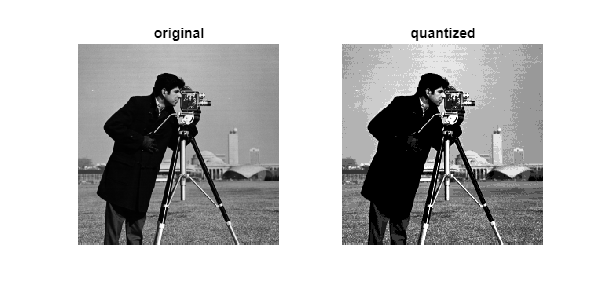

Img=imread('cameraman.tif');
levels = 10; % quantization level
thresh=multithresh(Img,levels);
Img_q=imquantize(Img,thresh);

figure;
subplot(121);
imagesc(Img);
colormap(gray);
axis image;
axis off;
title('original');
subplot(122);
imagesc(Img_q);
colormap(gray);
axis image;
axis off;
axis equal;
title('quantized');
set(gcf,'Position',[100 100 600 300]);